# FFT - Fast Fourier Transform Recursive Idea

## Derivation the Radix-2 Decimation In Time (DIT ) FFT algorithm

Computational idea is as follows: instead of multiplying $N$-samples long signal by $N \times N$ DFT matrix, one divides signal samples into two $N/2$-samples long vectors, taking samples with even and odd indexes separately, and multiply them by $N/2 \times N/2$ DFT matrix. The $N$-samples long spectrum DFT is reconstructed from two DFT spectra with length $N/2$. This way number of multiplication is reduced by half. The sample even/odd partitioning operation is repeated many times, up to receiving vectors with 2 signal samples only. Then, many (exactly $N/2$) 2-point DFTs are performed (using $2 \times 2$ matrices). Next, 2-element DFT spectra are combined into 4-element ones, 4-element to 8-elements, 8-element to 16-element, and so on ... $(\log_2(N)-1)$ times ... up to obtaining the resultant $N$-element DFT spectrum.Thanks to this instead of $N \cdot N$ multiplications only $N \cdot \log_2 (N)$ ones are required. Calculations have a form of so-called  ``butterflies'': addition & subraction of two numbers (after multiplication of the second of them by some correction terms), that are iterated ``in-place'' upon the data..

The DFT is defined and even/odd samples are decomposed as follows (instead of "$n$" we are using "$2m$" in the first sum and with "$2m+1$" in the second)($k=0,1,2,...,N-1$):

$X^{(N)}(k) \;\;\;\; = \;\;\;\;  \sum_{n=0}^{N-1}{x(n)e^{-j \frac{2\pi}{N}kn}} \;\;\;\; = \;\;\;\; \sum_{m=0}^{\frac{N}{2}-1}{x(2m)e^{-j \frac{2\pi}{N/2}km}} + e^{-j 2\pi \frac{k}{N}} \cdot \sum_{m=0}^{\frac{N}{2}-1}{x(2m+1)e^{-j \frac{2\pi}{N/2}km}}$,


$$X^{(N)}(k)  \;\; = \;\; X_e^{(N/2)}(k)+e^{-j \frac{2\pi}{N} k} X_o^{(N/2)}(k)$$


Since the** complex-value exponential term is the same** in *even* and *odd* sum for "$k$" and "$N/2+k$" when $k=0,1,2,...,N/2-1$:

$e^{-j \frac{2\pi}{N/2} \left( \frac{N}{2} +k \right) n} = e^{-j \frac{2\pi}{N/2} \left( \frac{N}{2} n \right)} \cdot e^{-j \frac{2\pi}{N/2} \left( k n \right)} = e^{-j 2\pi n} \cdot e^{-j \frac{2\pi}{N/2} \left( k n \right)} = 1 \cdot e^{-j \frac{2\pi}{N/2} k n} = e^{-j \frac{2\pi}{N/2} k n }$,

therefore we can calculated both sums only for $k_1=0,1,...,N/2-1$ and copy obtained values for corresponding indexes $k_2=N/2, N/2+1, ...,N-1:$

$X^{(N)}(k) = [ X_e^{(N/2)}(k_1), \;\; X_e^{(N/2)}(k_1)] + e^{-j \frac{2\pi}{N} k}  \cdot [ X_o^{(N/2)}(k_1)  \;\; X_o^{(N/2)}(k_1) ]$.

The described idea is presented in figure below.

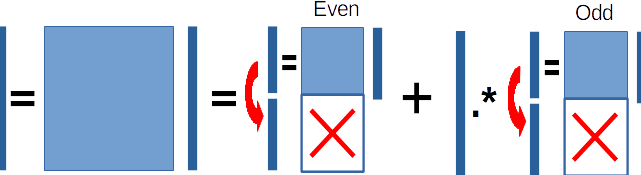

## Concept demonstration

**In Matlab, only as a demonstration**, we have:

clear all;                                              % clear all variables
N = 128; x = rand(1,N);                                 % analyzed signal, N=2^p
Xm = fft(x);                                            % its DFT (FFT) computed by Matlab 
Xe = fft(x(1:2:N));                                     % DFT of "even" samples
Xo = fft(x(2:2:N));                                     % DFT of "odd" samples
X = [ Xe, Xe ] + exp(-j*2*pi/N*(0:1:N-1)) .* [Xo, Xo ]; % combining two DFT spectra
error = max( abs( X - Xm ) ),                           % error

error = 3.2918e-15

## Recursive implementation

Repeating this operation in recursive manner many times, upto achieving pairs of two signal samples only, one obtains the recursive version of the **radix-2 **(samples partition into two pars)** DIT (decimation in time) FFT algorithm**. It is easy to write, but not very effective from the computation point of view (due to repeated signal partitioning and slow procesing of the succesive function calls by the operating system). Nevertheless, please, look below: the FFT idea is in hand.

**Analyze the Matlab code**. Find in the Internet description of the radix-4 DIT FFT algorithm and implement it as a recursive function. 

X = myRecFFT(x);                     % calling recursive function
error = max( abs( X - Xm ) ),        % error

error = 7.2292e-15

function X = myRecFFT(x)
% My recursive radix-2 FFT function
N = length(x);                       % number of signal samples 
if(N==2)                             % for 2 SIGNAL SAMPLES only
   X(1) = x(1) + x(2);                     % 2-point DFT
   X(2) = x(1) - x(2);                     % on the lowest level
else                                 % for MORE THAN 2 signal samples
   X1 = myRecFFT(x(1:2:N));                % call itself on even samples
   X2 = myRecFFT(x(2:2:N));                % call itself on odd samples
   X = [ X1 X1 ] + exp(-j*2*pi/N*(0:N-1)).* [X2 X2]; % combine even & odd spectra
end
end